## ESTIMACION DE ESTADO CON FILTROS DE LOCALIZACION (EKF, UKF Y MCL)

En este ejercicio, se simula un robot movil diferencial que se desplaza en un entorno 2D representado mediante un mapa de ocupacion binario. El robot disponde de sensores de odometria, GPS e IMU afectados por ruido gaussiano.

Se desea comparar el rendimiento de tres tecnicas de localizacion probabilistica:

- FIltro de Kalman Extendido (EKF)

- Filtro de Kalman Uscented (UKF)

- Localizacion Monte Carlo (MCL o AMCL) 

Se busca omplementar paso a paso las fases de predicción y corrección de las tres tecnicas anteriores,  y realizar un analisis de su comportamiento y los resultados obtenidos.

clear all; close all; clc
addpath(genpath('auxiliar'));

## DEFINICION DE RUTA

start = [5 35 0]; % [x, y, theta]
goal  = [22 3 0]; % [x, y, theta]

## CARGA DEL MAPA Y DEFINICIÓN DE RUTA

x0 = start(1);
y0 = start(2);

xf = goal(1);
yf = goal(2);

[mapOriginal, mapPlan] = cargar_mapa('complexMap',x0, y0, xf, yf); %complexMap

## PLANIFICACIÓN DE RUTA

waypoints = planificar_ruta(mapPlan, start, goal);

## CONTROLADOR ROBOT

controller = controlador_robot(waypoints);

## INICIALIZACION ALGORITMOS

% Inicialización de los estados reales y estimados, y de las covarianzas

% Estado real inicial (sin error)
x_true = [x0; y0; 0];

% Estado estimado inicial para EKF y UKF (con pequeño error inicial)
x_ekf = x_true + [0.2; -0.2; 0.05];
x_ukf = x_ekf;
x_mcl = x_ekf;

% Covarianza inicial del estimador (incertidumbre sobre x_ekf, x_ukf)
P_ekf = eye(3)*0.01;
P_ukf = P_ekf;

% Ruido de sensores (GPS y IMU)
Q_gps = diag([0.9, 0.9]).^2;  % Ruido en posición (metros^2)
Q_imu = deg2rad(20)^2;        % Ruido en orientación (radianes^2)
Q = blkdiag(Q_gps, Q_imu);    % Matriz de covarianza combinada del sensor

% Ruido del modelo de movimiento (odometría)
R_odom = diag([0.2, 0.2, 0.1]).^2;

% Parámetros del UKF
alpha = 1e-3;
beta = 2;
kappa = 0;
L = 3; % Dimensión del estado
lambda = alpha^2*(L + kappa) - L;
gamma = sqrt(L + lambda); % Escalado de los sigma points
wm = [lambda/(L + lambda), repmat(1/(2*(L + lambda)), 1, 2*L)];
wc = wm; wc(1) = wc(1) + (1 - alpha^2 + beta);

% Parametros MCL
N_particles = 300;
particles = repmat(x_ekf, 1, N_particles) + randn(3, N_particles) .* [0.2; 0.2; 0.1];
weights = ones(1, N_particles) / N_particles;
w_slow = 0;
w_fast = 0;
alpha_slow = 0.01; % Modificable por el alumno
alpha_fast = 0.1; % Modificable por el alumno


## SIMULACIÓN (NO MODIFICAR)

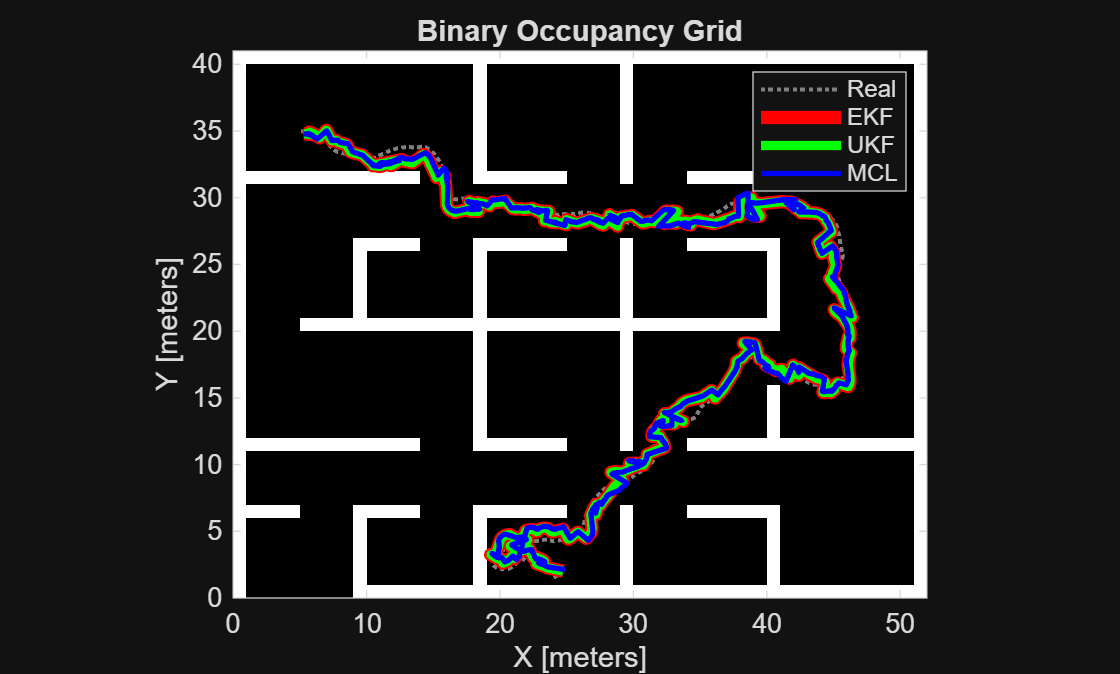

dt = 0.1;
maxSteps = 1000;
tol = 0.4;
gps_interval = round(1 / dt);  % 1 Hz

xHistEKF = zeros(3, maxSteps);
xHistUKF = zeros(3, maxSteps);
xHistMCL = zeros(3, maxSteps);
xTrueHist = zeros(3, maxSteps);
zIMUHist = zeros(1, maxSteps);
zGPSHist = nan(2, maxSteps);
odoHist = zeros(3, maxSteps);

latEKF = zeros(1, maxSteps); latUKF = zeros(1, maxSteps); latMCL = zeros(1, maxSteps);


figure; ax = axes;
show(mapOriginal, 'Parent', ax); hold(ax, 'on');
trajReal = animatedline('Color',[0.5 0.5 0.5] , 'LineStyle', ':', 'LineWidth', 1.5);
trajEstEKF = animatedline('Color', 'r', 'LineStyle', '-', 'LineWidth', 5);
trajEstUKF = animatedline('Color', 'g', 'LineStyle', '-', 'LineWidth', 3.5);
trajEstMCL = animatedline('Color', 'b', 'LineStyle', '-', 'LineWidth', 2);
legend('Real','EKF','UKF','MCL');

for k = 1:maxSteps

    z_control = simulate_sensors(x_true, Q_gps, Q_imu);
    [v, w] = controller(z_control');
    u = [v; w];
    x_true = motion_model(x_true, u, dt);

    if mod(k, gps_interval) == 0
        z = simulate_sensors(x_true, Q_gps, Q_imu);
    else
        gps_noise = [NaN; NaN];
        imu_noise = randn() * sqrt(Q_imu);
        z = [gps_noise; wrapToPi(x_true(3) + imu_noise)];
    end

    odo = motion_model(x_ekf, u, dt);

    % MCL
    t0 = tic;
    [particles, weights, x_mcl, w_slow, w_fast] = mcl_localization(particles, weights, u, z, R_odom, Q, dt, w_slow, w_fast, alpha_slow, alpha_fast);
    latMCL(k) = toc(t0);

    if all(~isnan(z(1:2)))
        % EKF
        t0 = tic;
        [x_ekf, P_ekf] = ekf_localization(x_ekf, P_ekf, u, z, R_odom, Q, dt);
        latEKF(k) = toc(t0);
        % UKF
        t0 = tic;
        [x_ukf, P_ukf] = ukf_localization(x_ukf, P_ukf, u, z, R_odom, Q, dt, gamma, wm, wc);
        latUKF(k) = toc(t0);
    else
        x_ekf = motion_model(x_ekf, u, dt);
        x_ekf(3) = wrapToPi(x_ekf(3));
        P_ekf = P_ekf + R_odom;

        x_ukf = motion_model(x_ukf, u, dt);
        x_ukf(3) = wrapToPi(x_ukf(3));
        P_ukf = P_ukf + R_odom;
    end

    xHistEKF(:,k) = x_ekf;
    xHistUKF(:,k) = x_ukf;
    xHistMCL(:,k) = x_mcl;
    xTrueHist(:,k) = x_true;
    zGPSHist(:,k) = z(1:2);
    zIMUHist(k) = z(3);
    odoHist(:,k) = odo;

    addpoints(trajReal, x_true(1), x_true(2));
    addpoints(trajEstEKF, x_ekf(1), x_ekf(2));
    addpoints(trajEstUKF, x_ukf(1), x_ukf(2));
    addpoints(trajEstMCL, x_mcl(1), x_mcl(2));

    if mod(k, 5) == 0
        drawnow; 
    end

    dist_ekf = norm(x_ekf(1:2) - goal(1:2)');
    dist_ukf = norm(x_ukf(1:2) - goal(1:2)');
    dist_mcl = norm(x_mcl(1:2) - goal(1:2)');
    
    if all([dist_ekf, dist_ukf, dist_mcl] < tol)
        disp("¡Ruta completada!");
        break;
    end

end

exportgraphics(ax, 'map_trajectory.png', 'Resolution', 800);

## GRÁFICAS COMPARATIVAS

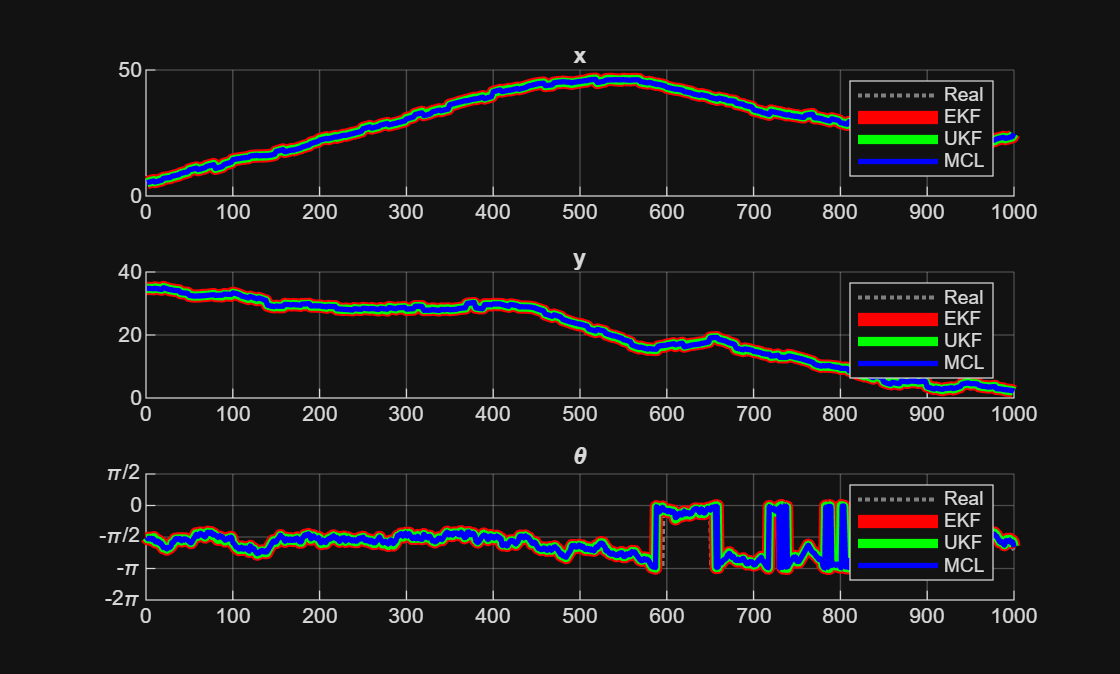

graficar_evolucion_estados(xTrueHist, xHistEKF, xHistUKF, xHistMCL, k, 'comparativa_x_y_theta.png')

## METRICAS


results = calcular_metricas(xTrueHist(:,1:k), ...
    struct('EKF', xHistEKF(:,1:k), 'UKF', xHistUKF(:,1:k), 'MCL', xHistMCL(:,1:k)), ...
    struct('EKF', P_ekf, 'UKF', P_ukf), ...
    Q, ...
    struct('EKF', latEKF(1:k), 'UKF', latUKF(1:k), 'MCL', latMCL(1:k)) ...
);

--- MÉTRICAS DE LOS ESTIMADORES ---

[EKF]
ATE:           0.7137 m
RPE:           0.0877 m
RMSE (full):   0.8309 m
RMSE (pos):    0.7953 m
Drift acumul.: 0.8337 m
Error final:   0.7736 m
STD Error:     0.3511 m
NEES:          2.3807
NIS:           1.2559
Latencia:      0.01 ms
Frecuencia:    93740.92 Hz

[UKF]
ATE:           0.7140 m
RPE:           0.0877 m
RMSE (full):   0.8312 m
RMSE (pos):    0.7957 m
Drift acumul.: 0.8342 m
Error final:   0.7716 m
STD Error:     0.3512 m
NEES:          2.3820
NIS:           1.2566
Latencia:      0.03 ms
Frecuencia:    36821.83 Hz

[MCL]
ATE:           0.7407 m
RPE:           0.1002 m
RMSE (full):   0.8594 m
RMSE (pos):    0.8274 m
Drift acumul.: 0.9889 m
Error final:   0.9405 m
STD Error:     0.3689 m
NEES:          NaN
NIS:           1.2883
Latencia:      0.94 ms
Frecuencia:    1069.37 Hz



guardar_formato_tum('truth.txt',     xTrueHist(:,1:k), dt);

Guardado en formato TUM: truth.txt


guardar_formato_tum('ekf_est.txt',   xHistEKF(:,1:k), dt);

Guardado en formato TUM: ekf_est.txt


guardar_formato_tum('ukf_est.txt',   xHistUKF(:,1:k), dt);

Guardado en formato TUM: ukf_est.txt


guardar_formato_tum('mcl_est.txt',   xHistMCL(:,1:k), dt);

Guardado en formato TUM: mcl_est.txt


## MODELO MOVIMIENTO

function x_new = motion_model(x, u, dt)
    v = u(1); w = u(2); theta = x(3);
    x_new = x + [v*cos(theta); v*sin(theta); w]*dt;
    x_new(3) = wrapToPi(x_new(3));
end

## SENSORES

function z = simulate_sensors(x, Q_gps, Q_imu)
    gps_noise = mvnrnd([0; 0], Q_gps)';
    imu_noise = randn() * sqrt(Q_imu);
    z = [x(1:2) + gps_noise; wrapToPi(x(3) + imu_noise)];
end

## EJERCICIO: EXTENDED KALMAN FILTER

function [x, P] = ekf_localization(x, P, u, z, R, Q, dt)

    % ==============================================
    % EJERCICIO: IMPLEMENTACIÓN DEL FILTRO EKF
    % ==============================================
    %
    % Entradas:
    %   x  - estado estimado en el instante anterior [x; y; theta]
    %   P  - matriz de covarianza del estado anterior (3x3)
    %   u  - vector de control [v; w] (velocidad lineal y angular)
    %   z  - observación medida [x_gps; y_gps; theta_imu]
    %   R  - matriz de covarianza del modelo de movimiento
    %   Q  - matriz de covarianza del sensor (GPS + IMU)
    %   dt - periodo de muestreo

    % ==============================================
    % 1. PREDICCIÓN DEL ESTADO Y COVARIANZA
    % ==============================================

    % 1.1. Extraer theta, v y w
    theta = x(3);
    v = u(1);
    w = u(2);

    % 1.2. Calcular la predicción del estado x_pred
    x_pred = x + [v*cos(theta); v*sin(theta); w]*dt;
    x_pred(3) = wrapToPi(x_pred(3));


    % 1.3. Derivar el Jacobiano F = df/dx
    F = [1 0 -v*sin(theta)*dt;
        0 1  v*cos(theta)*dt;
        0 0  1];


    % 1.4. Predicción de la nueva covarianza P_pred

    P_pred = F * P * F' + R;

    % ==============================================
    % 2. CORRECCIÓN CON OBSERVACIÓN
    % ==============================================

    % 2.1. Predicción de la observación z_pred
    z_pred = x_pred;

    % 2.2. Derivar la matriz de observación H
    H = eye(3);

    % 2.3. Calcular la innovación y = z - z_pred
    y = z(:) - z_pred;
    y(3) = wrapToPi(y(3));

    % 2.4. Calcular la covarianza de la innovación S
    S = H * P_pred * H' + Q;

    % 2.5. Calcular la ganancia de Kalman K
    K = P_pred * H' / S;

    % 2.6. Actualizar el estado estimado x
    % x = ...
    x = x_pred + K * y;
    x(3) = wrapToPi(x(3));

    % 2.7. Actualizar la covarianza estimada P
    % P = ...
    I = eye(3);
    P = (I - K*H) * P_pred * (I - K*H)' + K * Q * K';
end


## EJERCICIO: UNSCENTED KALMAN FILTER


function [x, P] = ukf_localization(x, P, u, z, R, Q, dt, gamma, wm, wc)
    % ======================================================
    % EJERCICIO: IMPLEMENTACIÓN DEL FILTRO UKF (Unscented)
    % ======================================================
    %
    % Entradas:
    %   x  - estado estimado en el instante anterior [x; y; theta]
    %   P  - matriz de covarianza del estado anterior
    %   u  - entrada de control [v; w]
    %   z  - observación [x_gps; y_gps; theta_imu]
    %   R  - matriz de covarianza del proceso
    %   Q  - matriz de covarianza del sensor
    %   dt - intervalo de tiempo
    %   gamma - parámetro de escalado
    %   wm, wc - pesos de media y covarianza para sigma points

    % ======================================================
    % 1. PREDICCIÓN
    % ======================================================

    % 1.1. Definir dimensiones del estado
    % Lx = ...;
    Lx = numel(x);              % 3
    x = x(:);
    z = z(:);

    % 1.2. Generar sigma points a partir de (x, P)
    % A = ...
    % X = ...
    P = (P + P')/2 + 1e-9*eye(Lx);
    A = chol(P, 'lower');
    X = [x, x + gamma*A, x - gamma*A];
    

    % 1.3. Propagar cada sigma point con el modelo de movimiento
    % for ...
    %     X_pred(:,i) = ...
    %     normaliza ángulo theta con wrapToPi
    % end
    nSig = size(X, 2);
    X_pred = zeros(Lx, nSig);
    for i = 1:nSig
        theta = X(3,i);
        v = u(1); w = u(2);
        X_pred(:,i) = X(:,i) + [v*cos(theta); v*sin(theta); w]*dt;
        X_pred(3,i) = wrapToPi(X_pred(3,i));
    end

    % 1.4. Calcular la media predicha del estado x_pred
    % x_pred = ...
    x_pred = zeros(Lx, 1);
    x_pred(1:2) = X_pred(1:2,:) * wm';
    x_pred(3) = atan2(sin(X_pred(3,:)) * wm', cos(X_pred(3,:)) * wm');

    % 1.5. Calcular la covarianza predicha del estado P_pred
    % P_pred = ...
    % for ...
    %     ...
    % end
    P_pred = R;
    for i = 1:nSig
        dx = X_pred(:,i) - x_pred;
        dx(3) = wrapToPi(dx(3));
        P_pred = P_pred + wc(i) * (dx * dx');
    end

    % ======================================================
    % 2. CORRECCIÓN
    % ======================================================

    % 2.1. Propagar sigma points al espacio de observación Z
    % Z = ...
    Z = X_pred;

    % 2.2. Calcular la media predicha de la observación z_pred
    % z_pred = ...
    z_pred = x_pred;
    

    % 2.3. Calcular covarianzas P_zz y P_xz
    % P_zz = ...
    % P_xz = ...
    % for ...
    %     ...
    % end
    P_zz = Q + R;
    P_xz = R;
    for i = 1:nSig
        dz = Z(:,i) - z_pred;
        dz(3) = wrapToPi(dz(3));
        dx = X_pred(:,i) - x_pred;
        dx(3) = wrapToPi(dx(3));
        P_zz = P_zz + wc(i) * (dz * dz');
        P_xz = P_xz + wc(i) * (dx * dz');
    end


    % 2.4. Calcular ganancia de Kalman
    % K = ...
    K = P_xz / P_zz;

    % 2.5. Actualizar el estado x y la covarianza P
    % y = ...
    % x = ...
    % P = ...
    y = z - z_pred;
    y(3) = wrapToPi(y(3));

    x = x_pred + K * y;
    x(3) = wrapToPi(x(3));

    P = P_pred - K * P_zz * K';
    P = (P + P')/2;    % fuerza simetría
end


## EJERCICIO: MONTE CARLO LOCALIZATION


function [particles, weights, x_est, w_slow, w_fast] = mcl_localization(particles, weights, u, z, R, Q, dt, w_slow, w_fast, alpha_slow, alpha_fast)
    % =========================================================================
    % EJERCICIO: IMPLEMENTACIÓN DEL MCL ADAPTATIVO CON INYECCIÓN DE PARTÍCULAS
    % =========================================================================
    % En este ejercicio, implementarás el Filtro de Partículas (Monte Carlo
    % Localization) incluyendo:
    %   - Predicción del estado de las partículas con movimiento + ruido
    %   - Corrección por sensor y ajuste de pesos
    %   - Resampleo adaptativo basado en pesos rápidos/lentos
    %   - Estimación del estado a partir de partículas
    
    % Entradas:
    %   particles: matriz 3xN con las partículas actuales [x; y; theta]
    %   weights: vector 1xN con los pesos actuales
    %   u: entrada de control [v; w]
    %   z: medición [x_gps; y_gps; theta_imu]
    %   R, Q: matrices de covarianza (movimiento y sensor)
    %   dt: paso de tiempo
    %   w_slow, w_fast: medias móviles del peso
    %   alpha_slow, alpha_fast: tasas de actualización de medias
    
    % Salidas:
    %   particles, weights: posterior al resampleo adaptativo
    %   x_est: estimación final del estado (media de partículas)
    %   w_slow, w_fast: medias móviles actualizadas
    
    % Número de partículas
    % N = ...;
    % w_avg = ...;
    z = z(:);
    N = size(particles, 2);
    v = u(1); w = u(2);
    
    % ==================================================
    % 1. PREDICCIÓN DEL ESTADO DE LAS PARTÍCULAS
    % ==================================================
    % for cada partícula
    %   - Aplicar modelo de movimiento
    %   - Añadir ruido de odometría
    %   - Asegurar que la orientación esté entre [-pi, pi]
    % end
    std_odom = sqrt(diag(R));   % R es covarianza -> desviación típica

    for i = 1:N
        theta = particles(3,i);
        % Modelo de movimiento
        particles(:,i) = particles(:,i) + [v*cos(theta); v*sin(theta); w]*dt;
        % Ruido de odometría
        particles(:,i) = particles(:,i) + std_odom .* randn(3,1);
        % Orientación en [-pi, pi]
        particles(3,i) = wrapToPi(particles(3,i));
    end
    
    % ==================================================
    % 2. CORRECCIÓN MEDIANTE SENSOR (CÁLCULO DE PESOS)
    % ==================================================
    % if la medición es válida
    %   for cada partícula
    %       - Calcular la diferencia entre medición y partícula
    %       - Estimar la verosimilitud con mvnpdf
    %   end
    %
    %   - Normalizar pesos
    %   - Calcular w_avg
    %   - Actualizar w_slow y w_fast con medias móviles
    %
    if all(~isnan(z(1:2)))

        % Diferencia medición - partícula (con ángulo normalizado)
        diff = z - particles;                 % 3 x N
        diff(3,:) = wrapToPi(diff(3,:));

        % Verosimilitud de cada partícula
        lik = mvnpdf(diff', zeros(1,3), Q)';  % 1 x N
        weights = weights .* lik;

        % Medias del peso (sobre los pesos SIN normalizar)
        w_avg = mean(lik);

        % Normalizar pesos (con protección ante underflow)
        if sum(weights) > 0 && all(isfinite(weights))
            weights = weights / sum(weights);
        else
            weights = ones(1,N) / N;
        end

        % Medias móviles slow / fast
        if w_slow == 0
            w_slow = w_avg;
            w_fast = w_avg;
        else
            w_slow = w_slow + alpha_slow * (w_avg - w_slow);
            w_fast = w_fast + alpha_fast * (w_avg - w_fast);
        end
    %   =================================================
    %   3. RE-MUESTREO ADAPTATIVO
    %   =================================================
    %   - Para cada partícula:
    %       - Con cierta probabilidad, inyectar una partícula aleatoria
    %       - En otro caso, seleccionar según pesos
    %   - Reemplazar partículas
    %   - Reinicializar pesos uniformemente
    % end
    p_inject = max(0, 1 - w_fast / w_slow);

    cdf = cumsum(weights);
    cdf(end) = 1;                         % evita problemas de redondeo
    new_particles = zeros(3, N);

    for i = 1:N
        if rand() < p_inject
            % Inyección: partícula aleatoria alrededor de la medición
            new_particles(:,i) = mvnrnd(z', Q)';
            new_particles(3,i) = wrapToPi(new_particles(3,i));
        else
            % Selección según pesos (ruleta)
            idx = find(rand() <= cdf, 1, 'first');
            new_particles(:,i) = particles(:,idx);
        end
    end

    particles = new_particles;
    weights = ones(1,N) / N; 
end
    % ==================================================
    % 4. ESTIMACIÓN FINAL DEL ESTADO
    % ==================================================
    % x_est = ...
    % Asegurar que la media angular sea consistente con atan2
    x_est = zeros(3,1);
    x_est(1:2) = particles(1:2,:) * weights';
    x_est(3) = atan2(sin(particles(3,:)) * weights', cos(particles(3,:)) * weights');

    end


